clear;
close all;
clc;

I = imread('Normal\153958345-153958392-001.BMP');
I = imresize(I, [200 NaN])

I = 200×162×3 uint8 array
I(:,:,1) =

   255   254   240   214   209   235   255   255   255   255   255   255   255   255   254   254   254   254   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   244   215   186   161   147   151   161   168   183   201   218   234   247   255   255   255   255   255   255   255   255   251   252   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   253   252   238   218   197   189   198   207   214   217   223   230   243   254   255   254   253   254   254   247   243   248   255   255   255   255  

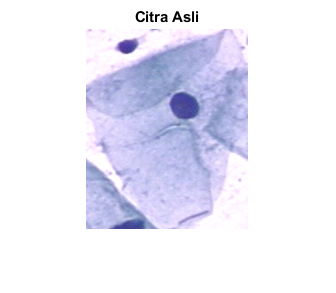

imshow(I), title('Citra Asli')

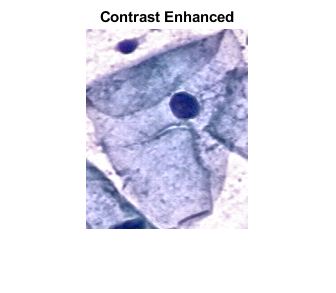

%convert RGB ke LAB
LAB = rgb2lab(I);

%skala fungsi adapthisteq
L = LAB(:,:,1)/100;
%CLAHE ke kanal L
L = adapthisteq(L,'NumTiles',[8 8],'ClipLimit',0.005);
LAB(:,:,1) = L*100;
%convert kembali citra lab ke rgb
M = lab2rgb(LAB);
figure, imshow (M), title('Contrast Enhanced')

level = graythresh(M)

level = 0.7020

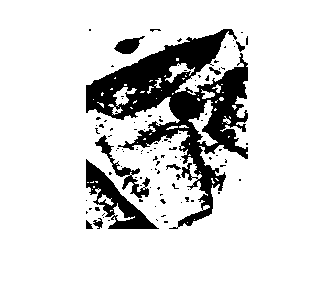

bw = im2bw(M, level);
imshow (bw)